# La trasformata di Fourier

Prendiamo un segnale campionato ad Fs = 1000Hz

clear
clc
close all
Fs = 1000; %Hz
T = 4; %durata del segnale
f0 = 50; %Hz

Generiamo il segnale

t = 0:1/Fs:T;
x = sawtooth(2*pi*f0*t,0.5)+ 0.1*randn(size(t));

Disegno il segnale nel tempo

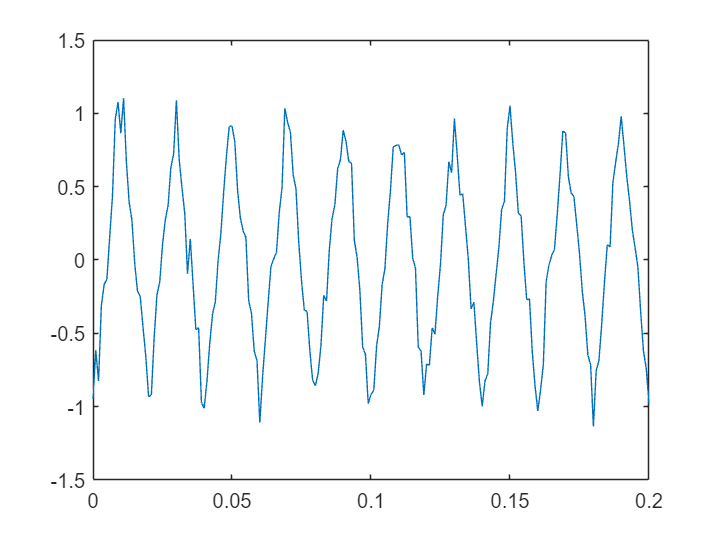

figure(1)
plot(t,x)
xlim([0 0.2])

Ora calcoliamo la trasformata di Fourier con la DFT

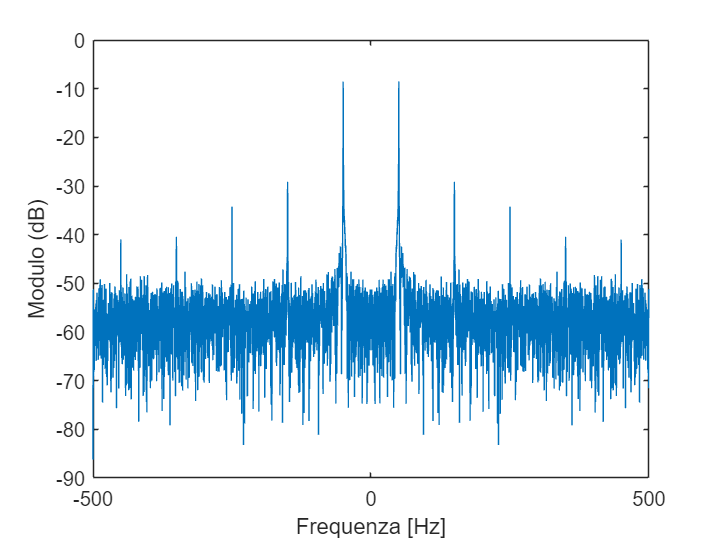

M = 4096;
X = fft(x, M)/M;
figure(2)
f = Fs/M*(0:M-1)';
plot(f-Fs/2, mag2db(abs(fftshift(X))))
xlabel('Frequenza [Hz]')
ylabel('Modulo (dB)')